params.mu = 0.10;
params.nu = 1.6;
params.lambda = 0;

params.fourier.order = 150; 
params.fourier.L = 50; 
params.fourier.tol = 1e-12; 

% Via Newton's method 
s_ic = [ -0.124918283636435 ; 0.191544405144654 ; 0.117983940139563 ; -0.205759977812573];
u_ic = [-0.190343484893489 ; -0.128234936941383 ; 0.193875175006471 ; 0.168311653800752];
disp('q_0 = ')

q_0 = 


----------------------------
----------------------------
Computing Fourier coeff for solution.


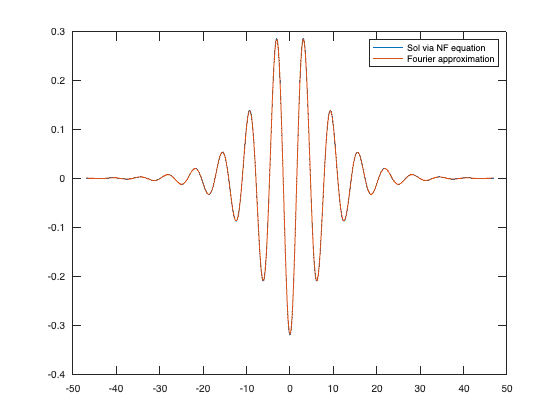

-----------------------------------------------
Performing Newtons method to refine the coefficients.
tolerance met
used iterations: 
     7
Error:
   3.0676e-13
These coefficients should be a zero of F.
Max elt F(a)=
   5.6295e-14
The nonnegative eigenvalues of DF are:
   0.176461517573894
   0.047896524831591
   0.000000000000613


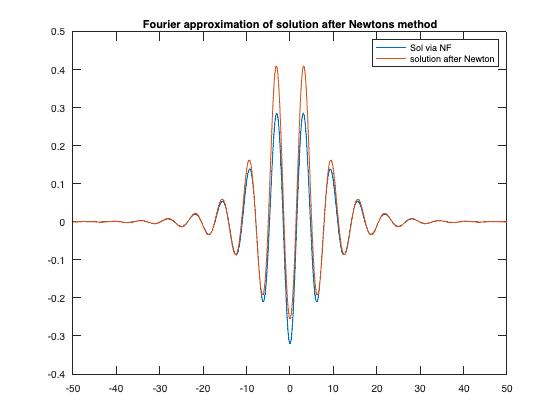


Niter = 10; 
step = .01; 

coeffs_pi = computeFourierSpectrumNFSol(params,pi, 0);

Tolerance met
Tolerance met
Tolerance met
Tolerance met
Tolerance met
Tolerance met
Tolerance met
Tolerance met
Tolerance met
Tolerance met


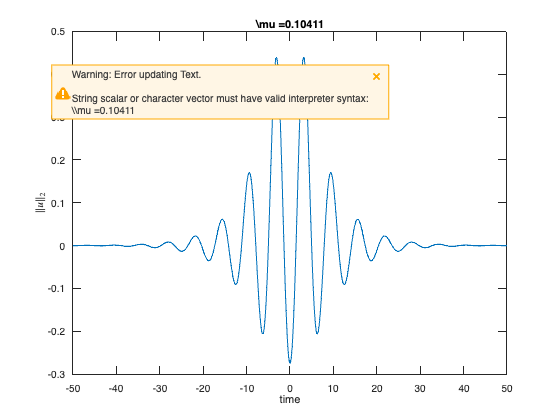

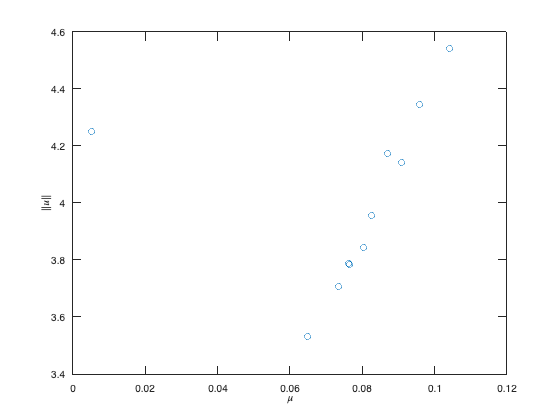


orig_params = params; 
orig_sol = coeffs_pi; 
params.mu = .005;

[branch_pi, norms_pi] = makeSolBranch(step, Niter, params, orig_sol);